clc;
clear;
I=imread('02-刘德华.jpg');
%将图像灰度化
I_gray=im2gray(I);
%寻找图像的中位数，就是二值化阈值
thresh=median(I_gray,"all");
disp(['二值化阈值为：',num2str(thresh)]);

二值化阈值为：14


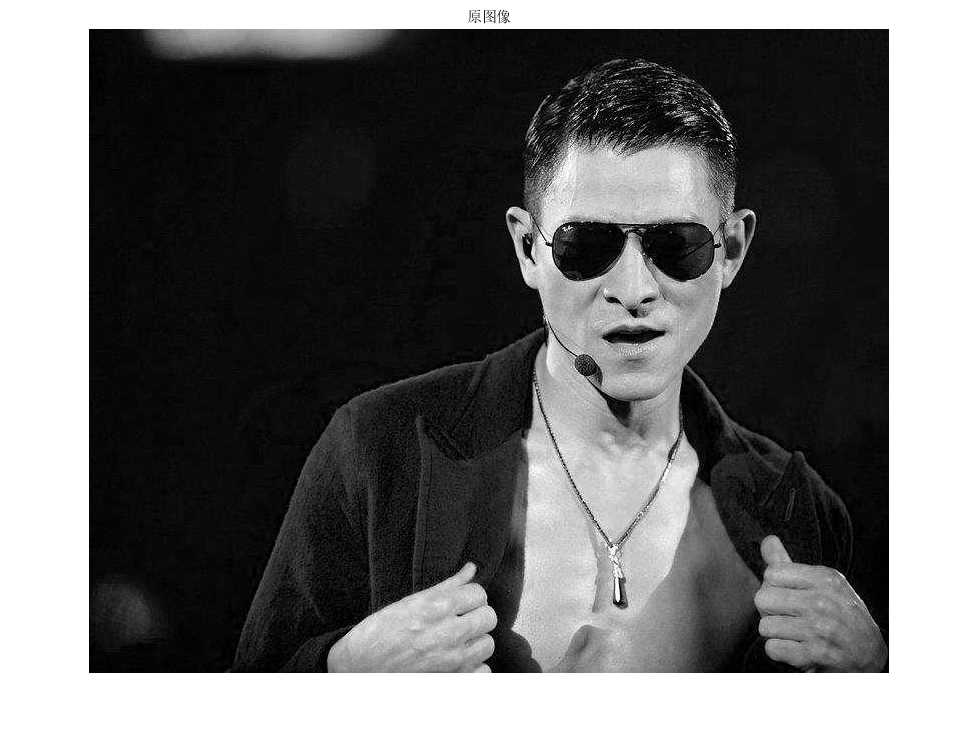

%灰度图二值化
I_bin=(I_gray>=thresh);
I_bin=I_bin*255;
figure
imshow(I);
title("原图像");

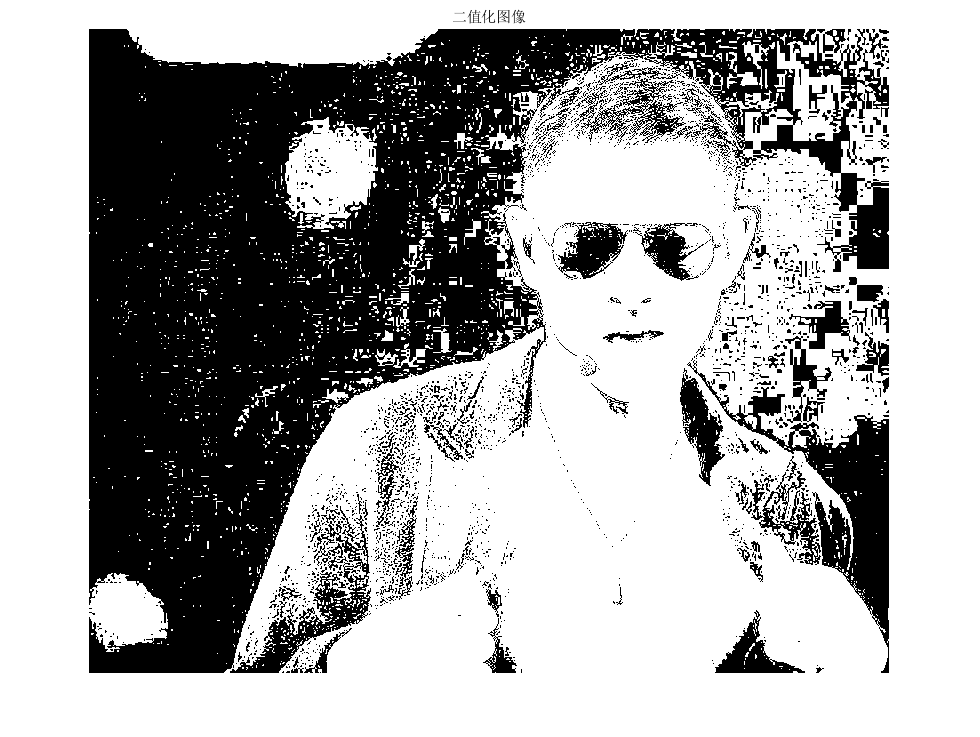

figure
imshow(I_bin);
title("二值化图像");

%保存图片
imwrite(I_bin,'二值化后的图片.jpg','jpg');